# TPA 4 Función Descriptiva Grupo 10

A contiunación se obtiene el modelo discrete en espacio de estados a partir del modelo de orden 6 obtenido en el TP1 (identificación)

close all; clc;
s = tf('s');

% addpath(genpath('...'));
% savepath

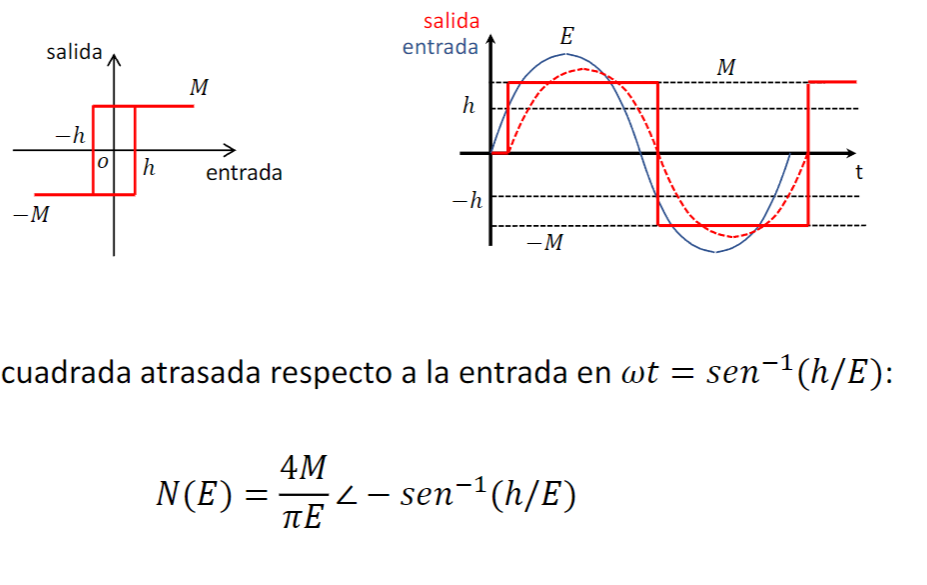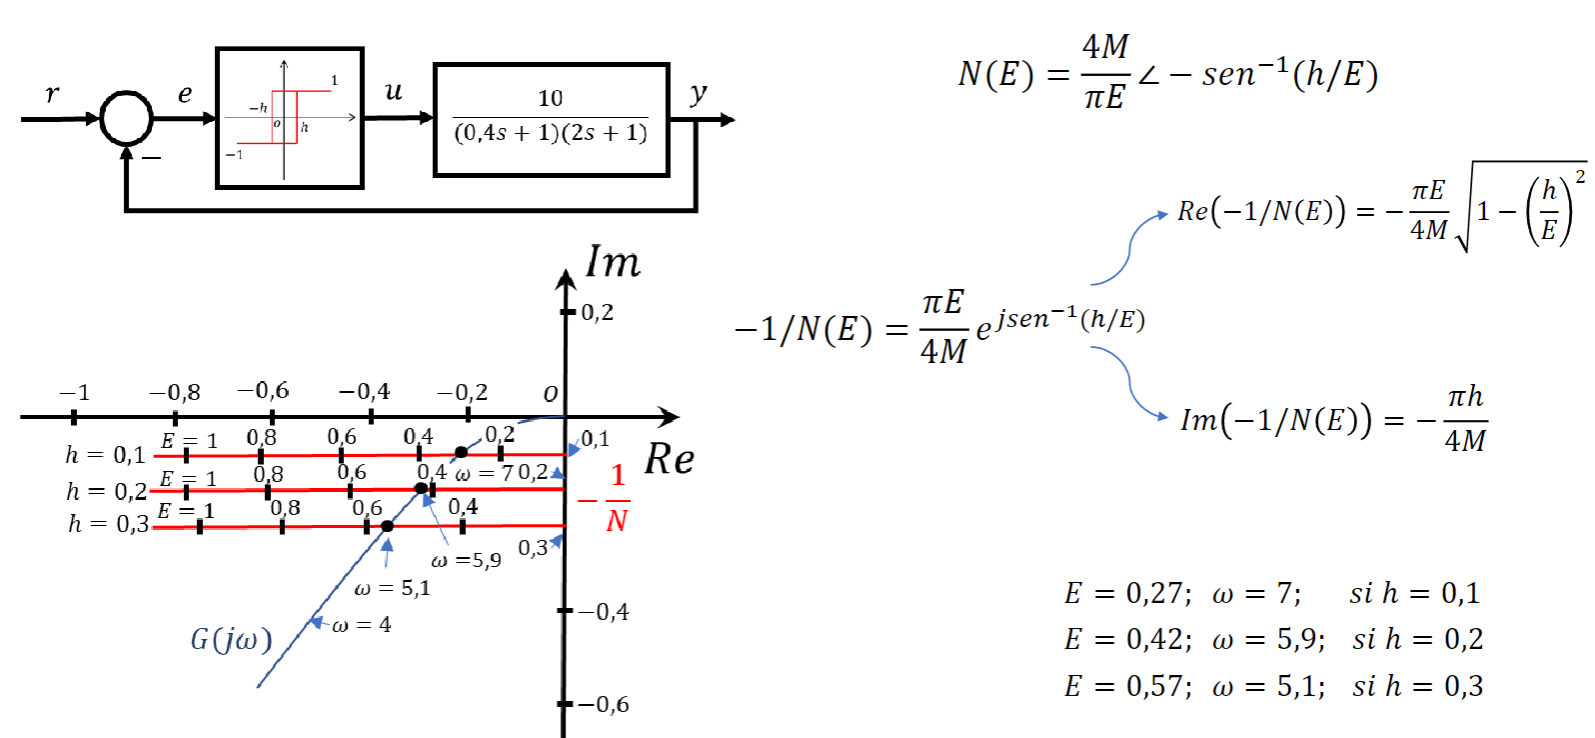

model_6 = 1/(( (10e3)*(10e-6)*s + 1 )^6)


model_6 =
 
                                   1
  --------------------------------------------------------------------
  1e-06 s^6 + 6e-05 s^5 + 0.0015 s^4 + 0.02 s^3 + 0.15 s^2 + 0.6 s + 1
 
Continuous-time transfer function.
Model Properties



[ny_r, ny_im, ny_w] = nyquist(model_6);
ny_r = reshape(ny_r, size(zeros(1, length(ny_r))));
ny_im = reshape(ny_im, size(zeros(1, length(ny_im))));
ny_w = reshape(ny_w, size(zeros(1, length(ny_w))));

M = 2.5;
h = 0.28191*4*M/pi

h = 0.8973

height = -pi*h/(4*M)

height = -0.2819


2*h

ans = 1.7947

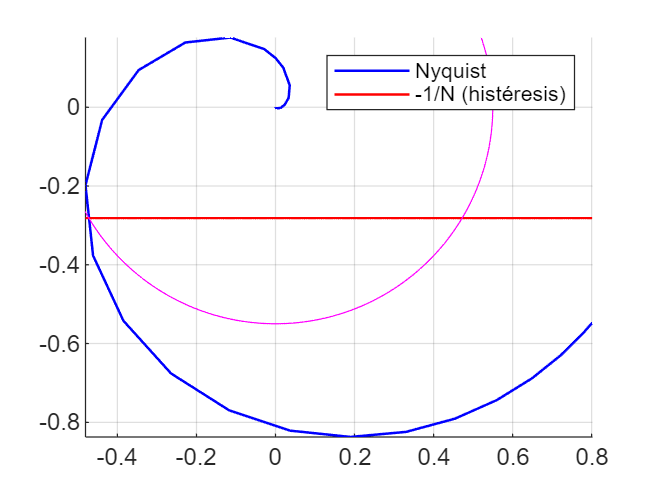


fig = figure;
hold on; grid on;

t = min(ny_r):1e-3:max(ny_r);
y = height*(ones(1, length(t)));
r = 0.5497787143;

plot(ny_r, ny_im, 'b', 'LineWidth', 1);
plot(t, y, 'r', 'LineWidth', 1);
plot(r*cos(0:1e-2:2*pi), r*sin(0:1e-2:2*pi), 'm');

xlim([min(ny_r), max(ny_r)]);
ylim([min(ny_im), max(ny_im)]);
legend('Nyquist', '-1/N (histéresis)');

Del gráfico se puede observar que la intersección está en (-0.443766, -0.0523599)

% fig = figure;
% nyquist(model_6)